# TP : Saé 22

alg de Karplus-Strong

sont suérieur a 10sec + effet pedale

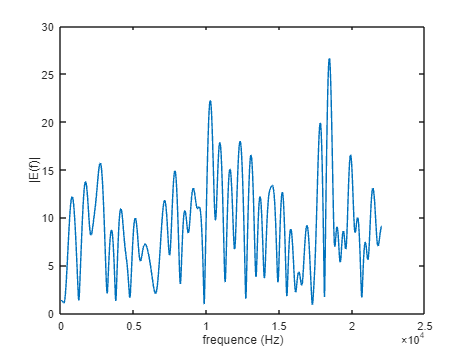

Fe = 44100;
F = 440;
d = 0.25;
L = round(Fe/F);
N =round(d*Fe);
e = randn(1,L); 
e =[e,zeros(1,N-L)];
E= abs(fft(e,2^nextpow2(length(e))));
E=E(1:end/2);
f=[0:length(E)-1]/length(E)*Fe/2;

plot(f,E);
xlabel('frequence (Hz)')
ylabel('|E(f)|')

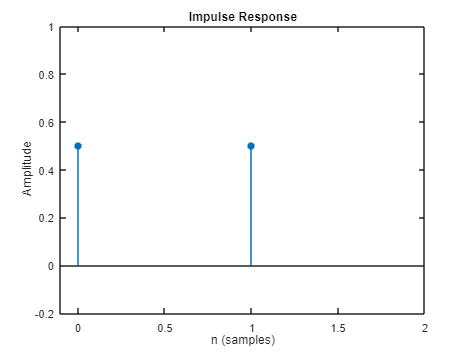


%filtre passe-bas
h=[1/2 1/2];
figure, impz(h); axis ([-0.1 2 -0.2 1]);

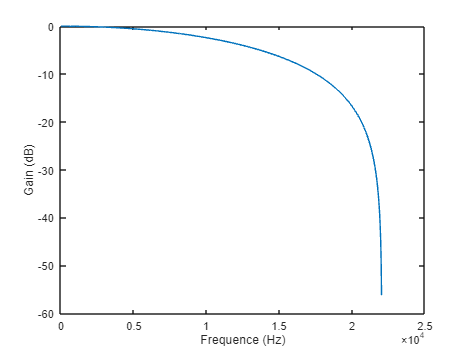


Nf = 1024;
[H,freq] = freqz(h,1,Nf,Fe);
plot(freq,20*log10(abs(H)));
xlabel('Frequence (Hz)'); ylabel('Gain (dB)');

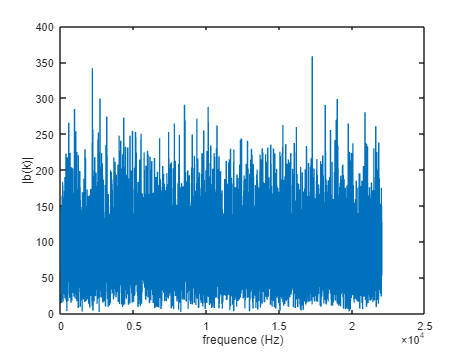

%freq rupture à -3DB = 11000Hz
L = round(Fe/F);
N =round(d*Fe);
b = randn(1,N); 
B= abs(fft(b,2^nextpow2(length(b))));
B=B(1:end/2);
f=[0:length(B)-1]/length(B)*Fe/2;

plot(f,B);
xlabel('frequence (Hz)')
ylabel('|b(k)|')

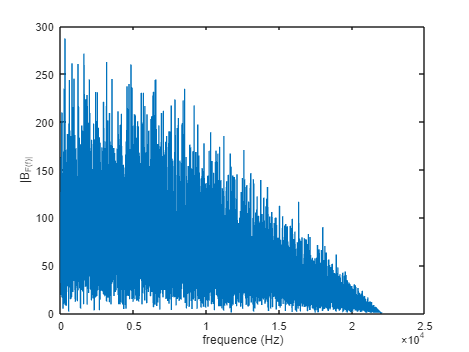


b= randn(1, N);
b_f(1)=b(1);
for k=2:length(b)
    b_f(k)=1/2*(b(k))+1/2*(b(k-1));
end

f=[0:length(b_f)-1]/length(b_f)*Fe/2;

B = abs(fft(b_f, 2^nextpow2(length(b_f))));
B_F = B(1:length(B)/2+1);
f = (0:length(B_F)-1)*(Fe/2)/length(B_F);

plot(f,B_F);
xlabel('frequence (Hz)')
ylabel('|B_F(f)|')